# Reef Images: Estimate and Apply Stereo Rectification

This script is adapted from the MATLAB example script. To run the original in 2024b or later: openExample('vision/EstimateAndApplyStereoRectificationExample').

Feature matching is drawn from the MATLAB SURF example: openExample('vision/visionrecovertform').

Changes effected by KD8OXT, 16 January 2025.

Load the stereo images and feature points which are already matched.

I1 = imread("reef_left.jpg");
I2 = imread("reef_right.jpg");
% I1 = imread("left_frame_000010976.jpg");
% I2 = imread("right_frame_000010976.jpg");

## Align images using SURF - obtain point correspondences

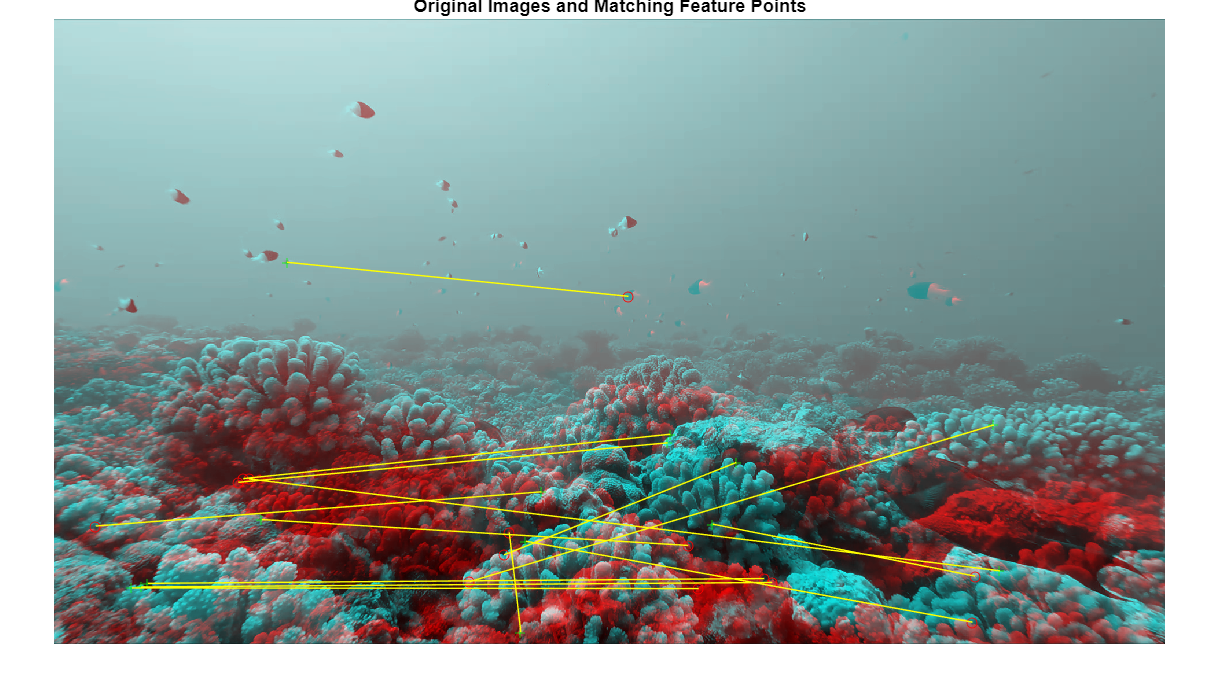

IM_L = rgb2gray(I1);
IM_R = rgb2gray(I2);
pts_L = detectSURFFeatures(IM_L);
pts_R = detectSURFFeatures(IM_R);

% Extract feature descriptors from the original and distorted features.
[features_L,validPts_L] = extractFeatures(IM_L,pts_L);
[features_R,validPts_R] = extractFeatures(IM_R,pts_R);
indexPairs = matchFeatures(features_L,features_R);

% Retrieve locations of corresponding points for each image.
matched_L = validPts_L(indexPairs(:,1));
matched_R = validPts_R(indexPairs(:,2));

% Show putative point matches.
figure
showMatchedFeatures(IM_L,IM_R,matched_L,matched_R);
title("Putatively matched points (including outliers)");

## Display point correspondences

Display point correspondences. Notice that the matching points are in different rows, indicating that the stereo pair is not rectified.

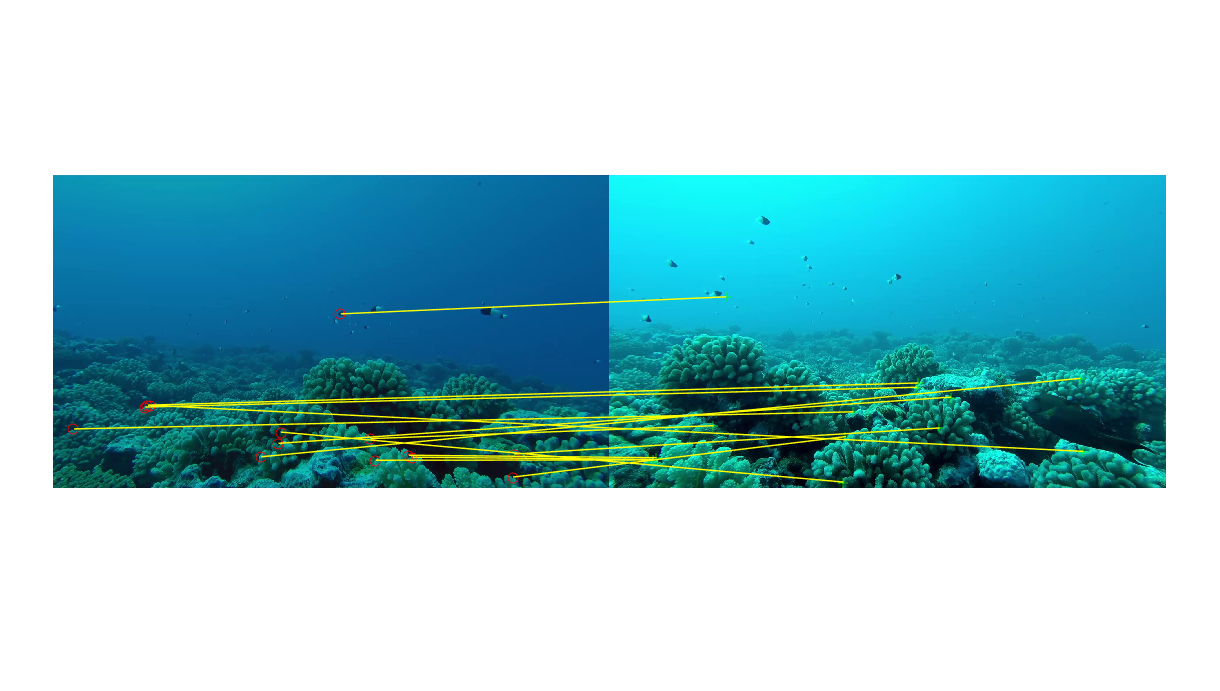

showMatchedFeatures(I1,I2,matched_L,matched_R,"montage");

title("Original Images and Matching Feature Points");

Calculate the fundamental matrix from the corresponding points.

f = estimateFundamentalMatrix(matched_L, matched_R, "Method","Norm8Point");

Calculate the rectification transformations.

[tform1,tform2] = estimateStereoRectification(f,matched_L,...
    matched_R,size(I2));

Rectify the stereo images using projective transformations `tform1` and `tform2`.

[I1Rect,I2Rect] = rectifyStereoImages(I1,I2,tform1,tform2);

Display the stereo anaglyph, which can also be viewed with 3-D glasses.

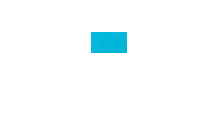

figure
imshow(stereoAnaglyph(I1Rect,I2Rect))

*Copyright 2022 The MathWorks, Inc.*